# Analysis of Covid-19 WHO data

opts = weboptions;
opts.ContentType = 'table';
by_date = webread("https://opendata.ecdc.europa.eu/covid19/casedistribution/csv",opts);
by_date.Properties.VariableNames = ["date", "day", "month", "year", "cases", "deaths", "location", "geo_id", "code", "population"];

Preview 10 random rows

by_date(randi(height(by_date),1,10), :)

ans = 10×10 table
       date       day    month    year    cases    deaths         location         geo_id     code      population
    __________    ___    _____    ____    _____    ______    __________________    ______    _______    __________

    26/01/2020    26       1      2020       0        0      {'United_Kingdom'}    {'UK'}    {'GBR'}    6.6489e+07
    13/02/2020    13       2      2020       0        0      {'Qatar'         }    {'QA'}    {'QAT'}    2.7817e+06
    23/01/2020    23       1      2020       0        0      {'Afghanistan'   }    {'AF'}    {'AFG'}    3.7172e+07
    12/01/2020    12       1      2020       0        0      {'Nig

latestDate = max(by_date.date)

latestDate = datetime
   01/04/2020


## Group by country 

[G,ID] = findgroups( by_date.location);
ID = categorical(ID);
by_country = table;
by_country.name = ID;

### Calculate Advanced Statistics

###  - Total cases & deaths

###  - 3 day rolling average

for n = 1:numel(ID)
    ix = find(G == n);
    by_date{ix,'total_deaths'}  = cumsum( by_date{ix,'deaths'}, 'reverse' );
    by_date{ix,'delta_death_growth_ratio'} = by_date{ix,'deaths'} ./ (by_date{ix,'total_deaths'} - by_date{ix,'deaths'});
    by_date{ix,'total_cases'}   = cumsum( by_date{ix,'cases'}, 'reverse' );
    by_date{ix,'delta_case_growth_ratio'} = by_date{ix,'cases'} ./ (by_date{ix,'total_cases'} - by_date{ix,'cases'});
    by_date{ix,'mov_avg_deaths'}  = movmean( by_date{ix,'deaths'}, 3, 'Endpoints', 'fill' );
end

by_country.total_deaths = splitapply( @max, by_date.total_deaths, G );
by_country.total_cases = splitapply( @max, by_date.total_cases, G );

### Find date of Nth death

N = 50;
by_country.date_deaths_N = splitapply( @(t,dt) findExeedanceDate(t,dt,N), by_date.date, by_date.total_deaths , G );

### Summary Statistics

maxDeaths = max(by_country.total_deaths);
maxCases = max(by_country.total_cases);
by_country = sortrows(by_country,'total_deaths','descend');

### Plot each country from date of Nth death

highlight = {'China' 'Italy' 'United_States_of_America' 'United_Kingdom' 'Spain'}

highlight = 1×5 cell array
    {'China'}    {'Italy'}    {'United_States_of_America'}    {'United_Kingdom'}    {'Spain'}


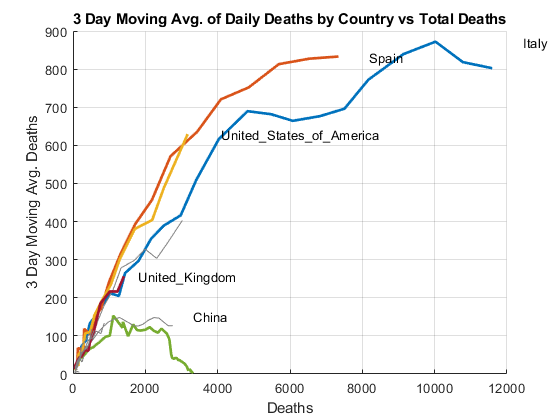


% Setup figure & axis
fig1 = figure;
ax1 = axes("NextPlot","add","YScale","log");
grid on
xlabel(ax1,"Days since " + num2str(N) + "th death")
ylabel(ax1,'Total deaths')
title( "Total deaths by country vs Date" )

fig2 = figure;
ax2 = axes("NextPlot","add");
grid on
xlabel(ax2,"Days since " + num2str(N) + "th death")
ylabel(ax2,'3 Day Moving Avg. Deaths')
title( "3 Day Moving Avg. of Daily Deaths by Country vs Date" )

fig3 = figure;
ax3 = axes("NextPlot","add");
grid on
xlabel(ax3,"Deaths")
ylabel(ax3,'3 Day Moving Avg. Deaths')
title( "3 Day Moving Avg. of Daily Deaths by Country vs Total Deaths" )

n = 0;
for id = by_country.name'
    n = n + 1;
    % Get single country summary
    country = by_country(by_country.name == id,:);
    
    % Index relevant data from main table
    ix = by_date.location == id & by_date.date >= country.date_deaths_N; 
    
    % Skip country if no relevant rows
    if ~any(ix); continue; end 
    
    % Calculate relative dates
    dt = by_date.date(ix) - country.date_deaths_N;
    total_deaths = by_date.total_deaths(ix);
    mov_avg_deaths = by_date.mov_avg_deaths(ix);
    
    % Plot rate of deaths
    y = total_deaths;
    if any(id == highlight)
        semilogy(ax1, dt, y, 'LineWidth', 2)
        text(ax1, max(dt), max(y), strrep(char(id), '_', '\_'))
    else
        semilogy(ax1, dt, y, 'Color', [0.5 0.5 0.5])
    end
    
    % Plot moving average
    y = mov_avg_deaths;
    if any(id == highlight)
        plot(ax2, dt, y, 'LineWidth', 2)
        text(ax2, max(dt), max(y), strrep(char(id), '_', '\_'))
    else
        plot(ax2, dt, y, 'Color', [0.5 0.5 0.5])
    end
    
    % Plot moving average vs deaths
    x = total_deaths;
    y = mov_avg_deaths;
    if any(id == highlight)
        plot(ax3, x, y, 'LineWidth', 2)
        text(ax3, max(x), max(y), strrep(char(id), '_', '\_'))
    else
        plot(ax3, x, y, 'Color', [0.5 0.5 0.5])
    end
    
end

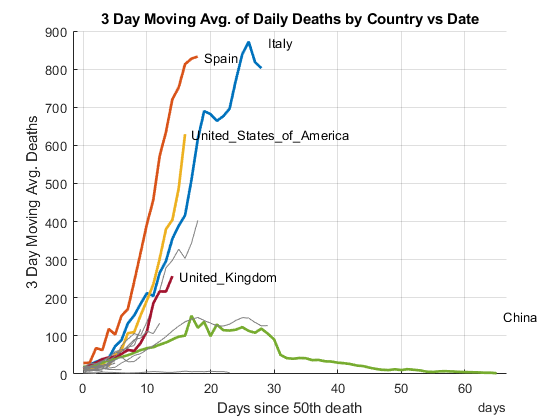

% Get time base
X = ax1.XTick;
xtickformat(ax1,'d')
xtickformat(ax2,'d')

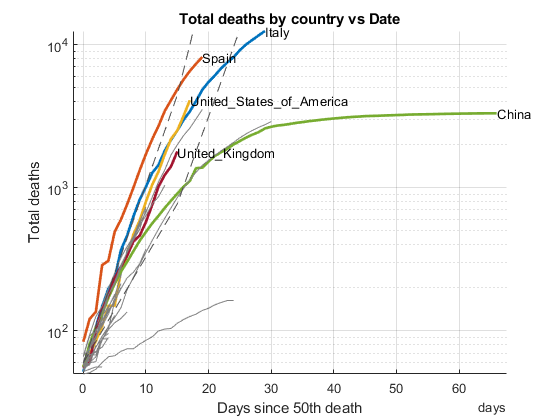

ax1.YLimMode = 'manual';
c = [0.3 0.3 0.3];

% Apply 33% growth line
Y = 10*(1.33).^days(X) + N;
semilogy(ax1, X, Y,'--','Color',c)

% Apply 50% growth line
Y = 10*(1.50).^days(X) + N;
semilogy(ax1, X, Y,'--','Color',c)

### UK Specific Data

country = by_country(by_country.name == "United_Kingdom",:)

country = 1×4 table
         name         total_deaths    total_cases    date_deaths_N
    ______________    ____________    ___________    _____________

    United_Kingdom        1789           25150        17-Mar-2020 


daily = by_date(by_date.location == "United_Kingdom",:);
ix = daily.date >= country.date_deaths_N;
daily = daily(ix,:);
latestDate = max(daily.date)

latestDate = datetime
   01/04/2020


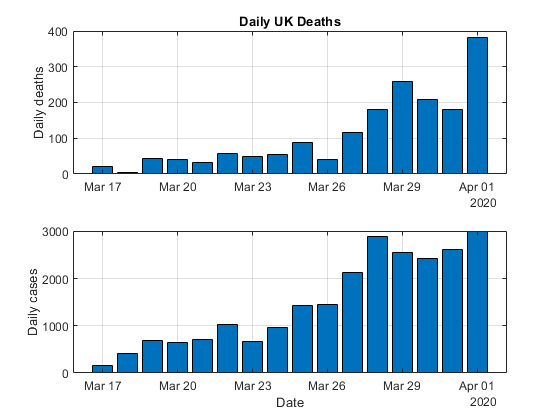

figure; 
ax = subplot(2,1,1); bar( ax, daily.date, daily.deaths );
grid on;
ylabel('Daily deaths');
title("Daily UK Deaths")
ax = subplot(2,1,2); bar( ax, daily.date, daily.cases );
grid on;
ylabel('Daily cases');
xlabel('Date');

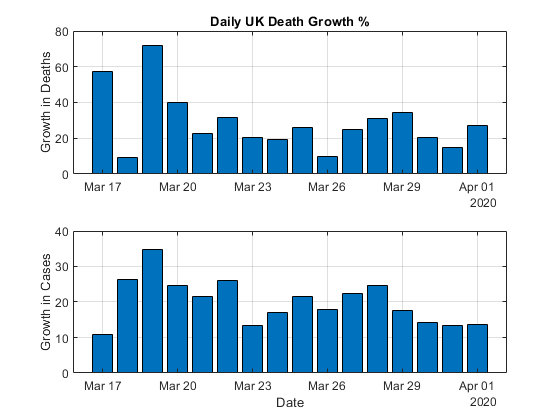

figure; 
ax = subplot(2,1,1); bar( ax, daily.date, daily.delta_death_growth_ratio * 100 );
grid on;
ylabel('Growth in Deaths');
title("Daily UK Death Growth %")
ax = subplot(2,1,2); bar( ax, daily.date, daily.delta_case_growth_ratio * 100);
grid on;
ylabel('Growth in Cases');
xlabel('Date');

function dt = findExeedanceDate( dates, value, threshold )
[dates,ix] = sort(dates,'ascend');
value = value(ix);

ix = value >= threshold;
if any(ix)
    dt = dates( find(ix,1) );
else
    dt = NaT;
end
end